%im = {'Covid (16).png','Covid (17).png','Covid (18).png','Covid (19).png','Covid (20).png','Covid (21).png','Covid (22).png','Covid (23).png','Covid (24).png','Covid (25).png','Covid (26).png','Covid (27).png','Covid (28).png','Covid (29).png','Covid (30).png','Covid (31).png','Non-Covid (17).png','Non-Covid (18).png','Non-Covid (19).png','Non-Covid (20).png','Non-Covid (21).png','Non-Covid (22).png','Non-Covid (23).png','Non-Covid (24).png','Non-Covid (25).png','Non-Covid (26).png','Non-Covid (27).png','Non-Covid (28).png','Non-Covid (29).png','Non-Covid (30).png','Non-Covid (31).png','Non-Covid (32).png','Covid (501).png','Covid (502).png','Covid (503).png','Covid (504).png', 'Non-Covid (501).png','Non-Covid (502).png','Non-Covid (503).png','Non-Covid (504).png'};
im = {'Covid (16).png','Covid (17).png','Covid (18).png','Covid (19).png','Covid (20).png','Covid (21).png','Covid (22).png','Covid (23).png','Covid (24).png','Covid (25).png','Covid (26).png','Covid (27).png','Covid (28).png','Covid (29).png','Covid (30).png','Covid (31).png','Non-Covid (17).png','Non-Covid (18).png','Non-Covid (19).png','Non-Covid (20).png','Non-Covid (21).png','Non-Covid (22).png','Non-Covid (23).png','Non-Covid (24).png','Non-Covid (25).png','Non-Covid (26).png','Non-Covid (27).png','Non-Covid (28).png','Non-Covid (29).png','Non-Covid (30).png','Non-Covid (31).png','Non-Covid (32).png'}

im = 1×32 cell array
    {'Covid (16).png'}    {'Covid (17).png'}    {'Covid (18).png'}    {'Covid (19).png'}    {'Covid (20).png'}    {'Covid (21).png'}    {'Covid (22).png'}    {'Covid (23).png'}    {'Covid (24).png'}    {'Covid (25).png'}    {'Covid (26).png'}    {'Covid (27).png'}    {'Covid (28).png'}    {'Covid (29).png'}    {'Covid (30).png'}    {'Covid (31).png'}    {'Non-Covid (17).png'}    {'Non-Covid (18).png'}    {'Non-Covid (19).png'}    {'Non-Covid (20).png'}    {'Non-Covid (21).png'}    {'Non-Covid (22).png'}    {'Non-Covid (23).png'}    {'Non-Covid (24).png'}    {'Non-Covid (25).png'}    {'Non-Covid (26).png'}    {'Non-Covid (27).png'}    {'Non-Covid (28).png'}    {'Non-Covid (29).png'}    {'Non-Covid (30).png'}    {'Non-Covid (31).png'}    {'Non-Covid (32).png'}


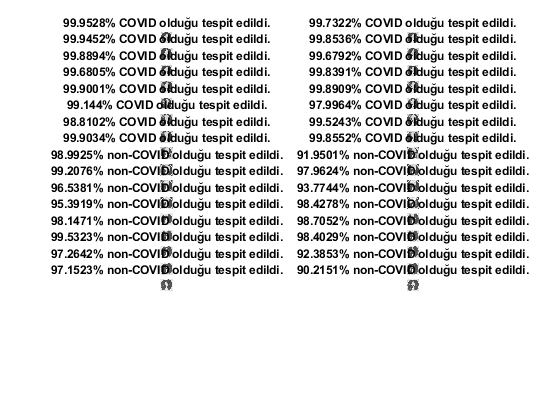



for k = 1:length(im)
     img = imread(im{k});
     image=imresize(img,[227 227]);
     [label,score] = classify(net,image);
     subplot(8,2,k);
     imshow(image);
     
     title(max(score)*100+"% " + string(label) + " olduğu tespit edildi.");
     hold on
     
end